# 足圧中心（Center of Pressure: CoP）動揺分析

※　Demo03 までは理解しておくこと

clear
close all
clc


% *** 実験実習で測定計測したデータ を load***
fileName = 'StandData_S01' ; % ←　被験者番号を指定する
load(fileName) ;

StandData = StandDataStruct.Normal_EC(1) ; % ←　条件名を指定する
condName = 'Normal_EC' ; % ← ここも一行上の条件名に対応させて書き換える
grfs = StandData.Forces ;

cop = StandData.CoP ;
% ****




## 時系列波形をプロット

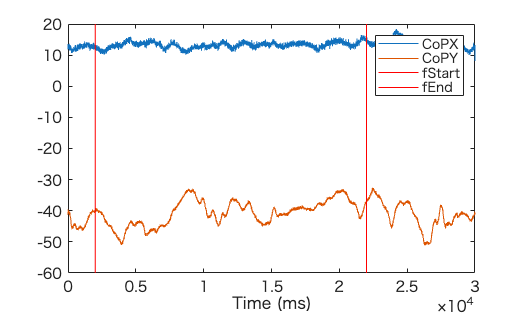

copX = cop(:,1) - ones(30000,1)*600 ;
copY = cop(:,2) - ones(30000,1)*200 ;

figure
plot(copX) ; hold on
plot(copY) ;
xlabel('Time (ms)')

% 分析区間を設定
% 静止立位のCoP動揺分析の場合、通常 20s 程度の区間を分析する
% "静止立位の定常状態"が保たれている区間を分析する必要がある
dur = 20000 ;
fStart = 2001 ;
fEnd = fStart + dur - 1 ; 

% 分析区間を図示
lineplot([fStart, fEnd], 'v', 'r') ;
legend({'CoPX', 'CoPY', 'fStart', 'fEnd'});

## CoPのxy平面プロット

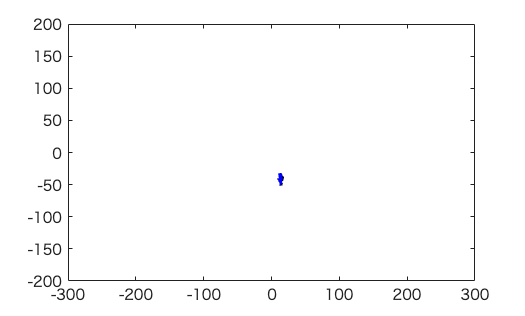

% 立位が維持できていない、等の異常がないか確認すること
if strcmp(condName,'Normal_EC') || strcmp(condName,'Normal_EO')
    figure
    plot(copX, copY, 'k') ; hold on
    plot(copX(fStart:fEnd), copY(fStart:fEnd), 'b')

    % axis equal % 横軸と縦軸のスケールを揃える
    set(gca, 'xlim', [-300,300], 'ylim', [-200,200])

elseif strcmp(condName,'Tandem_EC') || strcmp(condName,'Tandem_EO')
    figure
    plot(copY, copX, 'k') ; hold on
    plot(copY(fStart:fEnd), copX(fStart:fEnd), 'b')

    % axis equal % 横軸と縦軸のスケールを揃える
    set(gca, 'xlim', [-200,200], 'ylim', [-300,300])
end

## CoP 動揺指標の計算

簡便な指標として、以下の2つを計算

- CoP velocity: 単位時間あたりのCoP軌跡長。細かい修正を行う成分を多く反映すると言われている。

- CoP SD: 分析区間内のCoP時系列波形データの標準偏差, 前後方向・左右方向それぞれを計算する。低周波の大きな揺れの影響を強く受けると言われている。

※　いずれも、元波形のフィルター周波数の影響を強く受けるので、異なる文献間で数値を比較する際は注意すること。このフォルダ内のCoPデータは、カットオフ周波数が5 Hzの2次のバターワースフィルターゼロラグフィルター（MATLAB のfiltfilt関数）により平滑化されている。

参考：　Prieto (1996). Measures of postural steadiness: differences between healthy young and elderly adults. [https://pubmed.ncbi.nlm.nih.gov/9214811/](https://pubmed.ncbi.nlm.nih.gov/9214811/)


% CoP velocity: 単位時間あたりのCoP軌跡長 (mm/s)
copDis = sum(diff(cop).^2,2).^0.5 ; % 各時刻におけるCoP変位長
copVel = sum(copDis(fStart:fEnd-1)) / (dur/1000) 

copVel = 130.2850


% CoP SD
copSDAP = std(copY(fStart:fEnd))

copSDAP = 3.9381


% // 内外側方向のCoP SDを計算し、copSDML として定義しなさい //


% /////



## エキスポート用の構造体とテーブル

array editor から、テーブルの数値をコピーして Excel 等に貼り付けてもよいし、writetable関数を用いて、テーブルをcsvファイルに保存してもよい。

統計検定を行う前に、プロットを確認して、分析された数値が正しいものであるか、必ず確認すること

S.CoPVel = copVel ;
S.CoPSDAP = copSDAP ;
S.CoPSDML = copSDML ;

関数または変数 'copSDML' が認識されません。


T = struct2table(S)

